### Punto 7

Proponga 4 posturas (*x, y, z, roll, pitch, yaw*)*′ *que estén dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 1.  

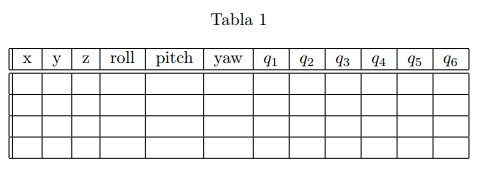

clc 
R1=([-30.326 26.760 -44.822]);  p1=[0.522 0.522 0.864];  Target1 = [p1,R1];
R2=[178.103 -1.289 -55.821];  p2=[0.498 0.7733 0.234];  Target2 = [p2,R2];
R3=[-154.184 40.52 46.130];  p3=[0.744 0.379 0.680];  Target3 = [p3,R3];
R4=[17.472 14.826 1.009];  p4=[0.498 -0.565 0.875];  Target4 = [p4,R4];

Q1 = inversa(Target1)*180/pi

Q1 =    45.0000   36.9326  -37.5766         0  -49.7748   82.8002


Q2 = inversa(Target2)*180/pi

Q2 =    57.2187   59.0791  -26.3682         0   54.9957    1.4186


Q3 = inversa(Target3)*180/pi

Q3 =    26.9947   30.5742  -22.5731         0   35.1804   82.7944


Q4 = inversa(Target4)*180/pi

Q4 =    45.0000   34.1886  -71.9402         0   24.5156  102.8963


Robot_ABB.fkine(Q1')

ans =     0.7304    0.4438    0.5192    0.0470
   -0.5293   -0.1126    0.8409    0.0761
    0.4316   -0.8890    0.1527    1.0495
         0         0         0    1.0000


Robot_ABB.fkine(Q2')

ans =     0.5836    0.2918    0.7578    0.4435
   -0.7987    0.0378    0.6005    0.3514
    0.1466   -0.9557    0.2551   -0.4178
         0         0         0    1.0000


Robot_ABB.fkine(Q3')

ans =     0.9504    0.2385   -0.1998    0.0799
   -0.0465    0.7438    0.6668   -0.2666
    0.3077   -0.6244    0.7179    0.2079
         0         0         0    1.0000


Robot_ABB.fkine(Q4')

ans =     0.8288   -0.3787    0.4119    0.3432
    0.0088    0.7449    0.6672    0.5558
   -0.5594   -0.5493    0.6207    0.1108
         0         0         0    1.0000


### Conclusión

Finalmente la tabla 1 queda definida como:

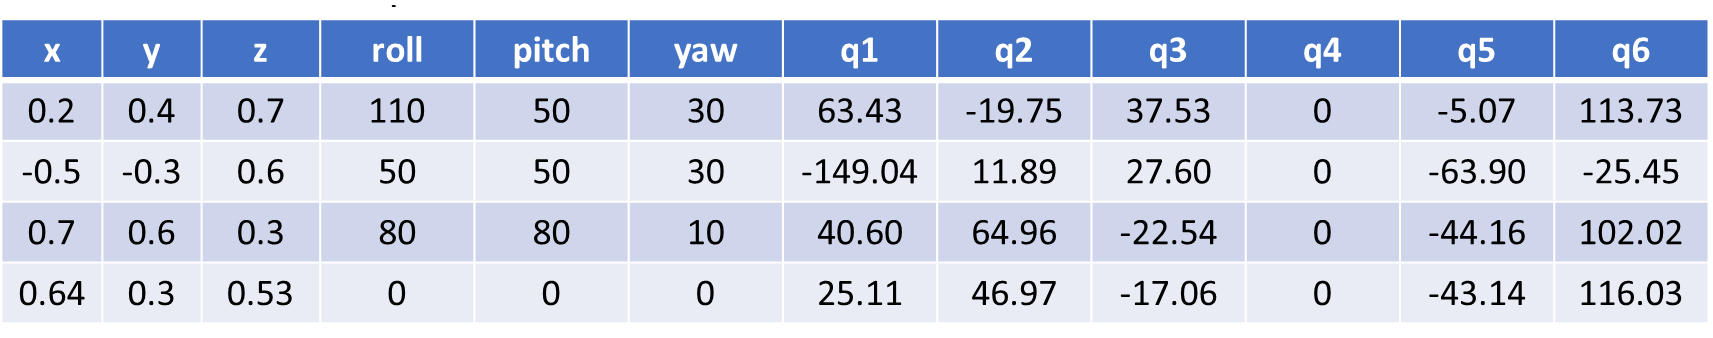

function Q = inversa(pose)   %angulos en grados
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6 
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.101; 
L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

pos_dada = [pose(1) pose(2) pose(3)];  %[0.522 0.522 0.864]; % Pos. Final Pedida
ori_dada = [pose(4) pose(5) pose(6)]*pi/180; %[-30.326 26.760 -44.822]*pi/180; % Ori. Final Pedida

% pos_dada = [0.498 0.7733 0.234]; % Pos. Final Pedida
% ori_dada = [178.103 -1.289 -55.821]*pi/180; % Ori. Final Pedida
% pos_dada = [0.744 0.379 0.680]; % Pos. Final Pedida
% ori_dada = [-154.184 40.52 46.130]*pi/180; % Ori. Final Pedida

q1 = atan2(pos_dada(2),pos_dada(1));

T_06 = transl(pos_dada)*rpy2tr(ori_dada);
m = (T_06*[0 0 1 1]')';
m(:,4) = [];
P = m-pos_dada;
phi_1 = atan2(P(3),sqrt(P(1)^2+P(2)^2));
%phi_1 = acos(-0.9992);
f = atan2(L5,L6);
h= phi_1+f;
P_65 = [cos(q1)*(cos(h)*sqrt(L5^2+L6^2)) sin(q1)*(cos(h)*sqrt(L5^2+L6^2)) sin(h)*sqrt(L5^2+L6^2)]; %P_65 = [-L5 0 -L6]; 
P_05 = pos_dada-P_65;
P_01 = [0 0 L1]; P_06 = pos_dada;
% 
% P_05 = P_06+P_65; %P_05 = (T_06*[P_65 1]')';
%P_05(:,4) = [];
P_15 = P_05-P_01;
a = P_15(1); b = P_15(2); c = P_15(3); 

sigma = atan2(L4,L3);
alpha = acos((-a^2-b^2-c^2+(L2^2+L3^2+L4^2))/(2*L2*sqrt(L3^2+L4^2)));
q3 = pi-sigma-alpha;

beta = atan2(c,sqrt(a^2+b^2));
gamma = acos((L2^2-L3^2-L4^2+a^2+b^2+c^2)/(2*L2*sqrt(a^2+b^2+c^2)));
q2 = pi/2-beta-gamma;

P_56_a = [cos(q1)*L6 sin(q1)*L6 L5];
ang_0 = atan2(P_65(3),sqrt(P_65(1)^2+P_65(2)^2));
ang_1 = atan2(P_56_a(3),sqrt(P_56_a(1)^2+P_56_a(2)^2));

q5 = -q2-q3+ang_1-ang_0;

%---------------------------
T_01 = L(1).A(q1);
T_12 = L(2).A(q2);
T_23 = L(3).A(q3);
T_34 = L(4).A(0);
T_45 = L(5).A(q5);
q6 = 0;
T_56 = L(6).A(q6);
T_06 = T_01*T_12*T_23*T_34*T_45*T_56;
RPY = tr2rpy(T_06);
q6 = -RPY(3)+ori_dada(3);


Q = [q1 q2 q3 0 q5 q6];
end